5a)

A = [1 4 4 ; 3 -1 3; -1 4 4];

f = @(x) sin(x);

sinA = schur_parlett(A,f)

sinA =     0.8023   -0.2700   -0.6142
    0.1201    0.4211   -0.3961
   -0.1691   -0.0980    0.5353



cosA = schur_parlett(A, @(x) cos(x))

cosA =     0.1541    0.6587    0.5495
    0.5964   -0.3390    0.4326
   -0.2397    0.7133    0.6277



expA = expm(1i*A)

expA =    0.1541 + 0.8023i   0.6587 - 0.2700i   0.5495 - 0.6142i
   0.5964 + 0.1201i  -0.3390 + 0.4211i   0.4326 - 0.3961i
  -0.2397 - 0.1691i   0.7133 - 0.0980i   0.6277 + 0.5353i



cosA + 1i*sinA

ans =    0.1541 + 0.8023i   0.6587 - 0.2700i   0.5495 - 0.6142i
   0.5964 + 0.1201i  -0.3390 + 0.4211i   0.4326 - 0.3961i
  -0.2397 - 0.1691i   0.7133 - 0.0980i   0.6277 + 0.5353i


5b)

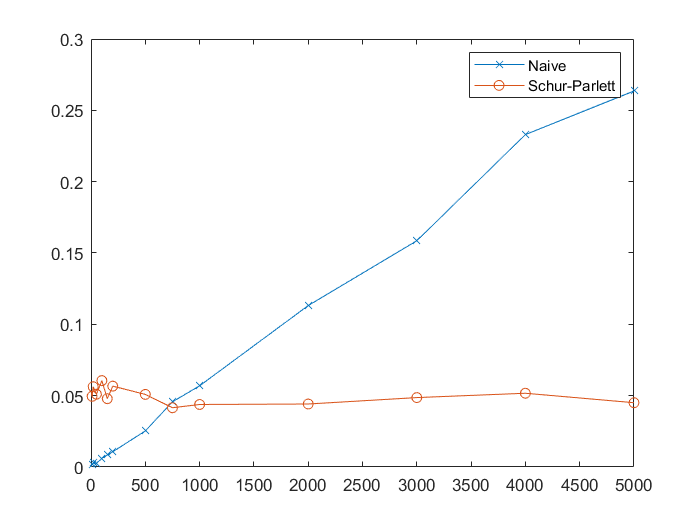

A = rand(100,100); A = A/norm(A);

B=A(:,:);


times_naive = [];
times_schur = [];

Ns = [10, 20, 50, 100, 150, 200, 500, 750, 1e3, 2e3, 3e3, 4e3, 5e3];

for j=1:length(Ns)
    
    N = Ns(j);
    pow = @(x) power(x, N);
    
    tic
    for i=1:N-1
        B=B*A;
    end
    t = toc;
    
    times_naive = [times_naive t];
    
    tic
    An = schur_parlett(A, pow);
    t = toc;
    
    times_schur = [times_schur t];

end


plot(Ns, times_naive, "-x");
hold on;
plot(Ns, times_schur, "-o");
legend("Naive", "Schur-Parlett")